# ECG SIGNAL ANALYSIS USING PCA AND VMD

# BL.SC.U4AIE24252

### GENERATE A SYNTHETIC ECG SIGNAL 

### A synthetic ECG waveform is created using a combination of sinusoids with different frequencies. Small random noise is added to make it realistic and the signal is normalized to have a uniform amplitude.

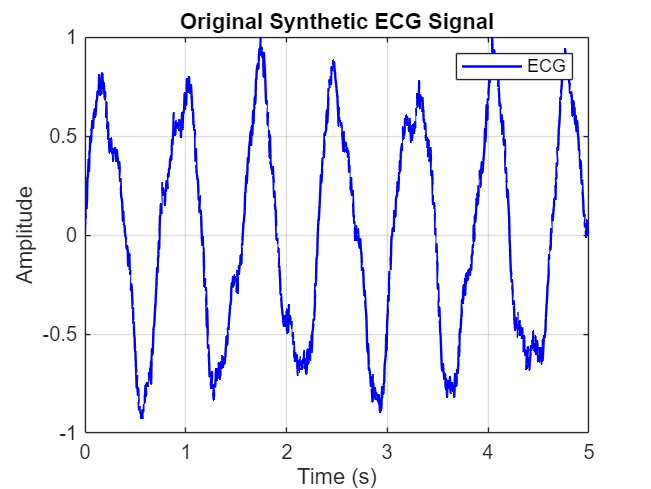

clear all; close all; clc;
fs = 250;                     
t = 0:1/fs:5;                 
N = length(t);                

ecg_signal = 1.2*sin(2*pi*1.3*t) + 0.25*sin(2*pi*3*t) + 0.1*sin(2*pi*7*t);
ecg_signal = ecg_signal + 0.05*randn(size(ecg_signal));
ecg_signal = ecg_signal / max(abs(ecg_signal));

figure(1)
plot(t, ecg_signal, 'b', 'LineWidth', 1.2);
title('Original Synthetic ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend('ECG');
grid on;

% This graph shows the ECG waveform in the time domain.

### DEFINE VMD PARAMETERS 

### The parameters for VMD are defined in this section. These parameters control how the signal is split into different frequency modes. The number of modes (K) determines how many separate components will be extracted from the ECG signal.

alpha = 2000;       
tau = 0;            
K = 3;              
DC = 0;             
init = 1;           
tol = 1e-7;         

### PERFORM VARIATIONAL MODE DECOMPOSITION (VMD)

### The ECG signal is decomposed into three modes using VMD. If the VMD function is not available, a dummy function is used to simulate the decomposition for demonstration purposes.

if exist('VMD', 'file')
    [u, u_hat, omega] = VMD(ecg_signal, alpha, tau, K, DC, init, tol);
else
    warning('VMD.m not found. Using dummyVMD() for demonstration.');
    [u, u_hat, omega] = dummyVMD(ecg_signal, alpha, tau, K, DC, init, tol);
end


if size(u,1) ~= length(ecg_signal)
    u = u';
end

### VISUALIZE THE DECOMPOSED MODES 

### The decomposed modes are plotted in this section. Each mode represents a part of the ECG signal that captures different frequency content. Together, these modes form the complete ECG waveform again.

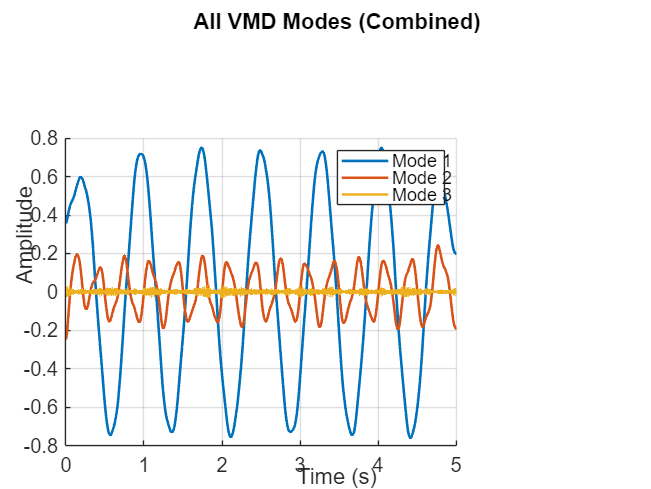

cmap = lines(K);

figure(2)
hold on;
for k = 1:K
    plot(t, u(:,k), 'Color', cmap(k,:), 'LineWidth', 1.3);
end
hold off;
title('All VMD Modes (Combined)');
xlabel('Time (s)');
ylabel('Amplitude');
legend(arrayfun(@(x) sprintf('Mode %d', x), 1:K, 'UniformOutput', false));
grid on;

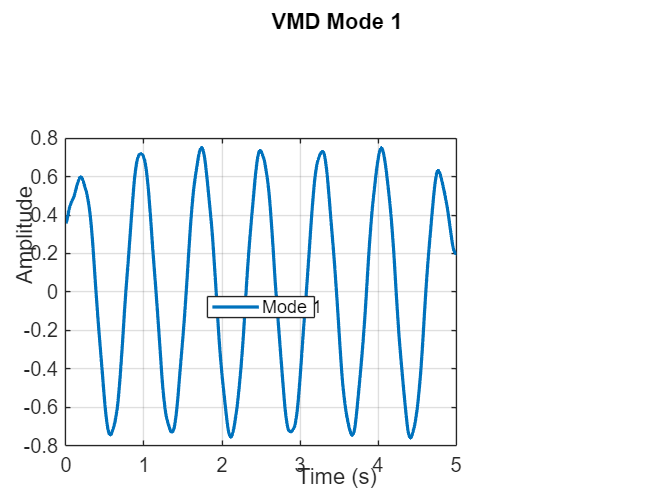

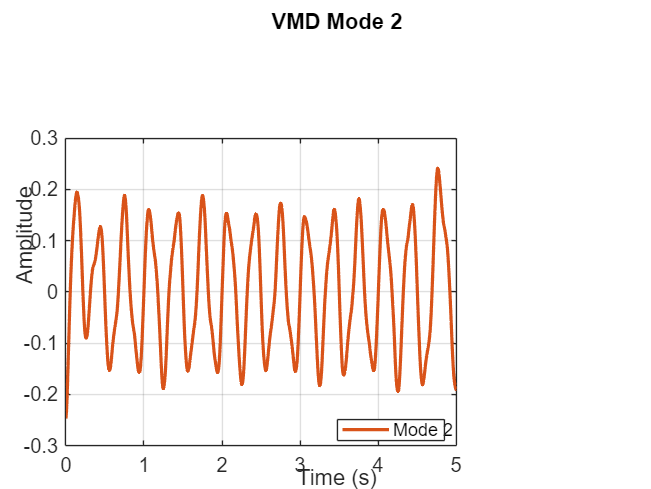

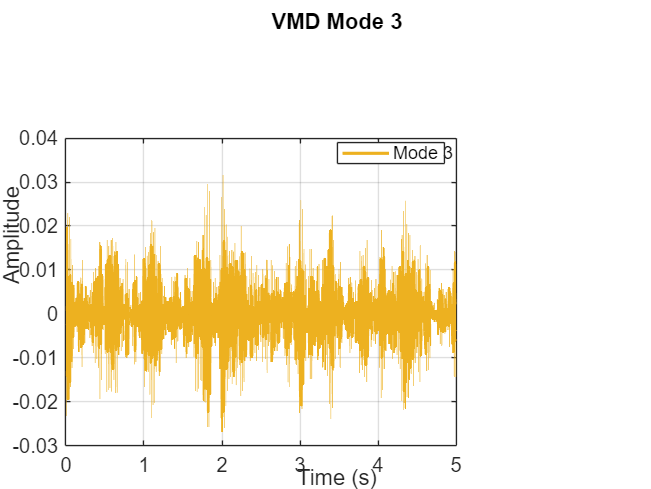

% This figure shows all three modes plotted together.

for k = 1:K
    figure(2 + k)
    plot(t, u(:,k), 'Color', cmap(k,:), 'LineWidth', 1.6);
    title(sprintf('VMD Mode %d', k));
    xlabel('Time (s)');
    ylabel('Amplitude');
    legend(sprintf('Mode %d', k), 'Location','best');
    grid on;
    % Each graph here shows one individual mode extracted by VMD.
end

### APPLY PRINCIPAL COMPONENT ANALYSIS (PCA) 

### PCA is applied on the extracted VMD modes. It reduces redundancy among the modes and identifies the major components that explain most of the signal variation. The ECG signal is then reconstructed using these principal components.

[coeff, score, latent, tsquared, explained, mu] = pca(u);
recon = score * coeff' + repmat(mu, size(u,1), 1);
recon_combined = sum(recon, 2);

### COMPARE ORIGINAL AND RECONSTRUCTED SIGNALS

### The reconstructed ECG signal is compared with the original ECG signal in the time domain to check how well PCA and VMDpreserved the original waveform.

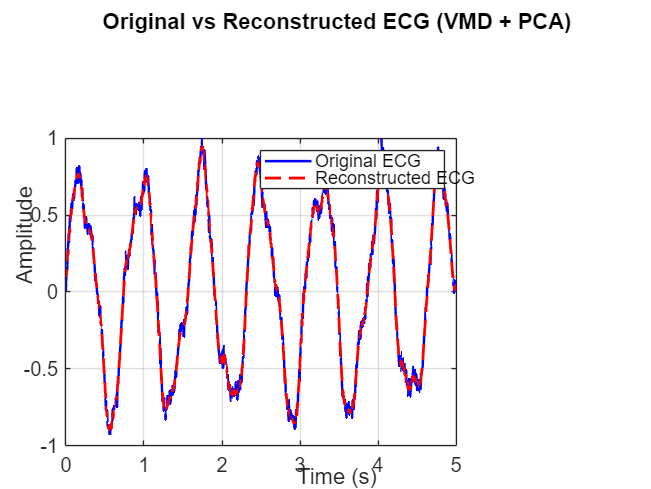

figure(6 + K)
plot(t, ecg_signal, '-b', 'LineWidth', 1.2); hold on;
plot(t, recon_combined, '--r', 'LineWidth', 1.4);
title('Original vs Reconstructed ECG (VMD + PCA)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original ECG', 'Reconstructed ECG');
grid on;

% This graph shows how closely the reconstructed ECG matches the original.

### TIME-FREQUENCY ANALYSIS USING SPECTROGRAMS

### The spectrogram shows how the frequency content of the ECG changes over time. This helps to see which frequencies dominate in different time intervals of the signal.

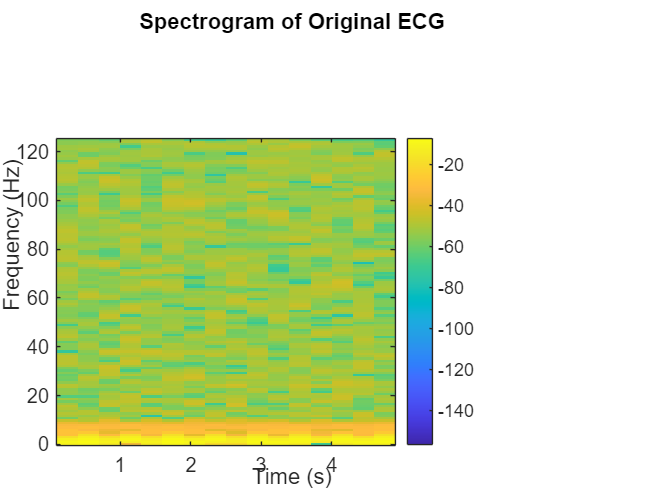

win_len = round(0.5 * fs);        
noverlap = round(0.4 * win_len);  

figure(7 + K)
spectrogram(ecg_signal, win_len, noverlap, [], fs, 'yaxis');
title('Spectrogram of Original ECG');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

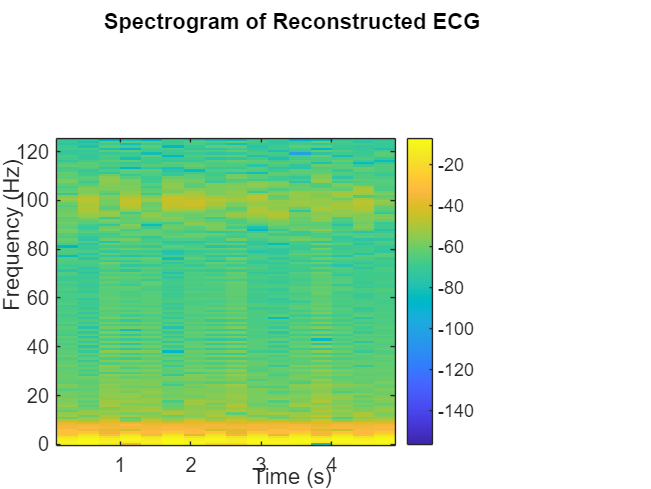

% This plot displays the time-frequency structure of the original signal.

figure(8 + K)
spectrogram(recon_combined, win_len, noverlap, [], fs, 'yaxis');
title('Spectrogram of Reconstructed ECG');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

% This plot shows how the frequency content is preserved after reconstruction.

### PERFORMANCE METRICS

### Correlation and RMSE values are calculated to measure the similarity between the original and reconstructed signals. A high correlation and low RMSE indicate accurate reconstruction.

R = corrcoef(ecg_signal, recon_combined);
RMSE = sqrt(mean((ecg_signal - recon_combined').^2));

disp('--- ECG Comparison Metrics ---');

--- ECG Comparison Metrics ---


if numel(R) >= 2
    disp(['Correlation (Original vs Reconstructed): ', num2str(R(1,2))]);
else
    disp('Correlation not available');
end

Correlation (Original vs Reconstructed): 0.99867


disp(['RMSE: ', num2str(RMSE)]);

RMSE: 0.027649


### Dummy VMD function 

### This function simulates how VMD separates a signal into multiple smooth modes at different frequency scales. It is not the real VMD algorithm and is only used for testing.

function [u, u_hat, omega] = dummyVMD(signal, alpha, tau, K, DC, init, tol)
    signal = signal(:);              
    N = length(signal);              
    t = linspace(0, 1, N)';          
    u = zeros(N, K);                 
    omega = linspace(2, 10, K);      

    for k = 1:K
        modulator = 0.5 + 0.5*sin(2*pi*omega(k)*t);
        u(:,k) = modulator .* signal;
    end
    
    u_hat = fft(u);  
end